%% Full scheduling for two-tone measurements avoiding DP and SNR-bin overlap
clearvars; close all; clc;

%% ---------- Parameters ----------
fs = 44100;
blockLength = 4096;
fRatio = 1.22;

f2cand = [500:500:1500 2000:1000:10000].';

dpCoeffs = [
    1  0;    % f1
    0  1;    % f2
    2 -1;    % 2*f1 - f2
   -1  2;
    1  1;
    3 -2;
   -2  3;
    2  1;
    1  2
];

exclBins = 5; %sidebins which are protected -+ for f1, f1 and 2f1-f2


%% ---------- Build f1 and f2 pairs ----------
pairs  = [f2cand./fRatio, f2cand];
nPairs = size(pairs,1);

nyq      = fs/2;
binWidth = fs/blockLength;
Nbins    = blockLength/2;

nDPs     = size(dpCoeffs,1);
freqsAll = nan(nPairs,nDPs);

for i = 1:nPairs
    freqs = dpCoeffs(:,1)*pairs(i,1) + dpCoeffs(:,2)*pairs(i,2);
    freqs(freqs<=0 | freqs>=nyq) = NaN;
    freqsAll(i,:) = freqs.';
end

binIdxAll = round(freqsAll/binWidth) + 1;
binIdxAll(isnan(freqsAll)) = NaN;

keepIdx = [1 2 3];   % f1, f2, 2f1-f2


% --- Protected bins per pair (f1, f2, 2f1-f2) ---
protectedBins = cell(nPairs,1);
for i = 1:nPairs
    win = false(1,Nbins);
    bins = binIdxAll(i,keepIdx);
    bins = bins(~isnan(bins));
    for b = bins
        lo = max(1,b-exclBins);
        hi = min(Nbins,b+exclBins);
        win(lo:hi) = true;
    end
    protectedBins{i} = find(win);
end


% --- All DP bins per pair ---
dpBins = cell(nPairs,1);
for j = 1:nPairs
    bins = binIdxAll(j,:);
    bins = bins(~isnan(bins) & bins>=1 & bins<=Nbins);
    dpBins{j} = unique(bins);
end

% --- Pairwise conflict matrix (Figures out which pairs can be measured at the same time)---
conflict = false(nPairs);
for i = 1:nPairs
    for j = i+1:nPairs
        if any(ismember(dpBins{j},protectedBins{i})) || ...
           any(ismember(dpBins{i},protectedBins{j}))
            conflict(i,j) = true;
            conflict(j,i) = true;
        end
    end
end

% --- Encode conflicts ---
confPairs = find(triu(conflict,1));
nConf     = numel(confPairs);

usesBin = false(nPairs,nConf);
[iList,jList] = ind2sub([nPairs nPairs],confPairs);

for k = 1:nConf
    usesBin(iList(k),k) = true;
    usesBin(jList(k),k) = true;
end

%% =========================================================================
%% Frequency Slot Pairings (read formulas in report)
%% =========================================================================

S      = nPairs;
numX   = nPairs*S;
numY   = S;
numVar = numX + numY;

f      = [zeros(numX,1); ones(numY,1)];
intcon = 1:numVar;

Aeq = sparse(nPairs,numVar);
beq = ones(nPairs,1);
for i = 1:nPairs
    Aeq(i,(i-1)*S+(1:S)) = 1;
end

% --- bin conflicts ---
nRows_bin = size(usesBin,2)*S;
row_i = []; col_j = []; val_v = [];

r = 0;
for s = 1:S
    for b = 1:size(usesBin,2)
        users = find(usesBin(:,b));
        if isempty(users), continue; end
        r = r+1;
        for k = 1:numel(users)
            row_i(end+1,1) = r;
            col_j(end+1,1) = (users(k)-1)*S + s;
            val_v(end+1,1) = 1;
        end
    end
end

A_bin = sparse(row_i,col_j,val_v,r,numVar);
b_bin = ones(r,1);

% --- linking ---
A_link = sparse(nPairs*S,numVar);
r = 0;
for i = 1:nPairs
    for s = 1:S
        r = r+1;
        A_link(r,(i-1)*S+s) = 1;
        A_link(r,numX+s)    = -1;
    end
end
b_link = zeros(nPairs*S,1);

A = [A_bin; A_link];
b = [b_bin; b_link];

lb = zeros(numVar,1);
ub = ones(numVar,1);

opts = optimoptions('intlinprog','Display','off','RelativeGap',1e-3);

fprintf('Solving with %d pairs, %d conflicts...\n',nPairs,nConf);

Solving with 12 pairs, 11 conflicts...


[xsol,~,exitflag] = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub,opts);

%% ---------- Interpret solution ----------
if exitflag>0
    xmat = reshape(xsol(1:numX),S,nPairs).';
    usedSlots = find(xsol(numX+1:end)>0.5);

    groups = cell(numel(usedSlots),1);
    for k = 1:numel(usedSlots)
        groups{k} = find(xmat(:,usedSlots(k))>0.5);
    end
    fprintf('optimal found: %d slots used.\n',numel(groups));
else
    error('slot pairing failed');
end

optimal found: 3 slots used.



% --------------Output resulting schedule and details -------------------
fprintf('\nSchedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):\n');


Schedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):


for s = 1:numel(groups)
    idxs = groups{s}(:).';
    fprintf('Slot %d: %d pairs -> indices: ', s, numel(idxs));
    fprintf('%d ', idxs);
    fprintf('\n');
    disp(array2table([idxs.' pairs(idxs,:) 2*pairs(idxs,1)-pairs(idxs,2)], ...
        'VariableNames',{'globalIdx','f1_Hz','f2_Hz','DP_2f1_minus_f2_Hz'}));
    % Show bins reserved per pair (for debugging)
    fprintf(' Reserved bins per pair (example first 3 DPs):\n');
    for ii = idxs
        used = find(usesBin(ii,:));
        fprintf('  pair %2d: reserved bins count = %d, center DP bins: ', ii, numel(used));
        centers = binIdxAll(ii, ~isnan(binIdxAll(ii,:)));
        fprintf('%d ', centers);
        fprintf('\n');
    end
    fprintf('---\n');
end

Slot 1: 4 pairs -> indices: 

3 10 11 12 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        3        1229.5     1500          959.02      
       10        6557.4     8000          5114.8      
       11          7377     9000          5754.1      
       12        8196.7    10000          6393.4      



 Reserved bins per pair (example first 3 DPs):


  pair  3: reserved bins count = 4, center DP bins: 

115 140 90 165 255 65 191 369 394 

  pair 10: reserved bins count = 0, center DP bins: 

610 744 476 878 1353 342 1012 1962 

  pair 11: reserved bins count = 2, center DP bins: 

686 837 535 988 1522 385 1138 

  pair 12: reserved bins count = 1, center DP bins: 

762 930 595 1097 1691 427 1265 

---


Slot 2: 4 pairs -> indices: 

1 6 7 8 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        1        409.84     500           319.67      
        6        3278.7    4000           2557.4      
        7        4098.4    5000           3196.7      
        8          4918    6000           3836.1      



 Reserved bins per pair (example first 3 DPs):


  pair  1: reserved bins count = 3, center DP bins: 

39 47 31 56 86 22 64 124 132 

  pair  6: reserved bins count = 1, center DP bins: 

306 373 239 440 677 172 507 982 1049 

  pair  7: reserved bins count = 3, center DP bins: 

382 465 298 549 846 214 633 1227 1310 

  pair  8: reserved bins count = 1, center DP bins: 

458 558 357 659 1015 257 759 1472 1572 

---


Slot 3: 4 pairs -> indices: 

2 4 5 9 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        2        819.67    1000           639.34      
        4        1639.3    2000           1278.7      
        5          2459    3000             1918      
        9        5737.7    7000           4475.4      



 Reserved bins per pair (example first 3 DPs):


  pair  2: reserved bins count = 2, center DP bins: 

77 94 60 111 170 44 127 246 263 

  pair  4: reserved bins count = 2, center DP bins: 

153 187 120 220 339 86 254 491 525 

  pair  5: reserved bins count = 1, center DP bins: 

229 280 179 330 508 129 380 736 787 

  pair  9: reserved bins count = 2, center DP bins: 

534 651 417 768 1184 299 886 1717 1834 

---


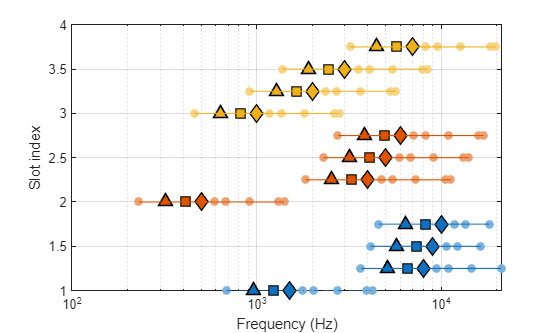

% ---------- Simple visualization (highlights main freqs f1,f2,DP=2f1-f2) ----------
figure('Name','Scheduled groups (frequencies)');
hold on;

% Slot colors
nSlots = max(1,numel(groups));
colors = lines(nSlots);

% Marker shapes for roles
markerMain = {'s','d','^'};         % markers for f1,f2,DP
roleNames = {'f1','f2','2f1-f2'};

% visual params
alphaFactor = 0.45;        % how faded the "other" frequencies are (0..1)
mainMarkerSize = 9;
otherMarkerSize = 6;
mainLineWidth = 1.2;

for s = 1:numel(groups)
    idxs = groups{s}(:);
    baseColor = colors(mod(s-1,size(colors,1))+1,:);
    fadedColor = (1-alphaFactor)*baseColor + alphaFactor*[1 1 1]; % fade toward white

    for k = 1:numel(idxs)
        i = idxs(k);
        fRow = freqsAll(i, :);
        valid = ~isnan(fRow);
        fRow = fRow(valid);
        y = s + (k-1)/max(1,numel(idxs));  % small vertical offset per pair

        % identify main frequencies for this pair
        f1 = pairs(i,1);
        f2 = pairs(i,2);
        dp = 2*f1 - f2;

        % Plot "other" frequencies (all valid except the three mains) as faded markers
        isMain = abs(fRow - f1) < 1e-9 | abs(fRow - f2) < 1e-9 | abs(fRow - dp) < 1e-9;
        others = fRow(~isMain);
        if ~isempty(others)
            plot(others, y*ones(size(others)), 'o', ...
                'Color', fadedColor, 'MarkerFaceColor', fadedColor, 'MarkerSize', otherMarkerSize);
        end

        % Plot main frequencies with distinct shapes but colored by slot
        plot(f1, y, markerMain{1}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(f2, y, markerMain{2}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(dp, y,  markerMain{3}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);

        % Connect all frequencies for this pair with a thin line in slot color
        if numel(fRow) > 1
            fRowSorted = sort(fRow);
            plot(fRowSorted, y*ones(size(fRowSorted)), '-', 'Color', baseColor, 'LineWidth', 0.8);
        end
    end
end

set(gca,'xscale','log');
xlabel('Frequency (Hz)');
ylabel('Slot index');
grid on; box on;

% Legend:
% - slot color patches
% - role markers
legendHandles = gobjects(0);
legendLabels = {};

% slot color entries (show up to first 10 slots to avoid huge legends)
maxLegendSlots = min(nSlots, 10);
for s = 1:maxLegendSlots
    h = plot(nan, nan, 's', 'MarkerFaceColor', colors(s,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 8);
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = sprintf('Slot %d', s); %#ok<SAGROW>
end

% role markers
for r = 1:numel(markerMain)
    h = plot(nan, nan, markerMain{r}, 'MarkerSize', mainMarkerSize, ...
        'MarkerEdgeColor','k', 'MarkerFaceColor', [0 0 0]); % black face for role legend
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = roleNames{r}; %#ok<SAGROW>
end

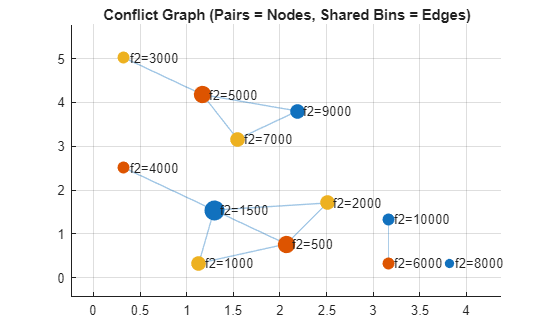




% ---------- Build conflict graph ----------------------------------------

% Nodes = pairs
% Edge between i and j if they share ANY bin
nPairs = size(usesBin,1);

% Initialize adjacency matrix
adjMat = false(nPairs);

for b = 1:size(usesBin,2)
    users = find(usesBin(:,b));
    if numel(users) > 1
        % Create all pairwise connections (clique)
        for k1 = 1:numel(users)
            for k2 = k1+1:numel(users)
                i = users(k1);
                j = users(k2);
                adjMat(i,j) = true;
                adjMat(j,i) = true;
            end
        end
    end
end

% Create graph object
G = graph(adjMat);

% ---------- Plot graph ----------
figure('Name','Conflict Graph');
hold on;

% Layout (force-directed gives good structure)
p = plot(G, 'Layout','force');

title('Conflict Graph (Pairs = Nodes, Shared Bins = Edges)');

% ---------- Color nodes by slot assignment ----------
if exist('groups','var')
    nSlots = numel(groups);
    colors = lines(nSlots);

    nodeColors = zeros(nPairs,3); % RGB per node

    for s = 1:nSlots
        idxs = groups{s};
        nodeColors(idxs,:) = repmat(colors(s,:), numel(idxs), 1);
    end

    p.NodeColor = nodeColors;
end


p.MarkerSize = 6 + 2*degree(G);  % bigger nodes = more conflicts
p.LineWidth = 0.5;
p.EdgeAlpha = 0.4;

% Label nodes with pair index
p.NodeLabel = arrayfun(@num2str, 1:nPairs, 'UniformOutput', false);

% ---------- annotate with f2 frequencies ----------
 labels = arrayfun(@(i) sprintf('f2=%.0f', pairs(i,2)), 1:nPairs, 'UniformOutput', false);
 p.NodeLabel = labels;

grid on;